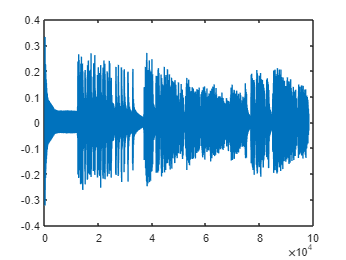

clear
load long_modem_rx.mat

start_idx = find_start_of_signal(y_r,x_sync);

y_t = y_r(start_idx+length(x_sync):end);
y_t = y_t(1:msg_length*8*100);
plot(y_t)

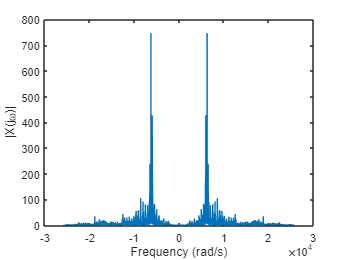

ans = 1.0e+02 *

   0.0029 + 0.0000i
   0.0031 - 0.0017i
   0.0037 + 0.0017i
  -0.0021 + 0.0032i
  -0.0030 + 0.0045i
  -0.0036 - 0.0006i
  -0.0024 - 0.0006i
   0.0016 - 0.0043i
   0.0048 + 0.0006i
   0.0005 + 0.0026i


plot_ft_rad(y_t, Fs)

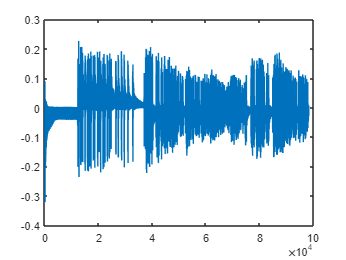


c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
y_t = c.*y_t;

plot(y_t)

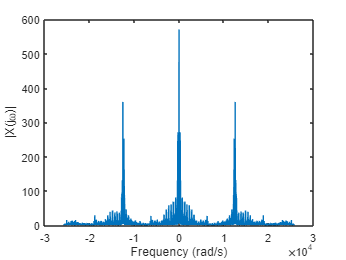

ans = 1.0e+02 *

   0.0169 + 0.0000i
  -0.0154 - 0.0072i
   0.0005 - 0.0097i
   0.0130 + 0.0011i
   0.0127 - 0.0059i
  -0.0052 + 0.0102i
  -0.0031 + 0.0096i
   0.0029 + 0.0140i
   0.0081 - 0.0053i
  -0.0092 + 0.0011i


plot_ft_rad(y_t, Fs)


cutoff_freq = 100; 
order = 5

order = 5

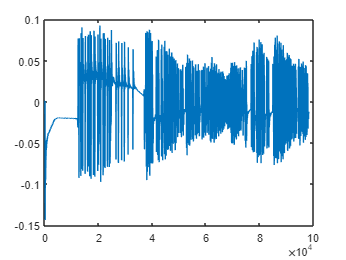

[B, A] = butter(order, cutoff_freq / (Fs / 2), 'low');
filtered_signal = filter(B, A, y_t);

plot(filtered_signal)



% Extract portion of the signal for decoding
plus_minus_one = sign(filtered_signal(1:100:98400));
zeros_ones_signal = (plus_minus_one + 1) * 0.5;

% Extract actual signal for decoding
act_signal = zeros_ones_signal(1:984);

% Convert to String
BitsToString(act_signal)

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ..'


% Low Pass Filter
%t = [-50:50]*1/Fs;
%W = 2*pi*f_c;
%h = W/pi*sinc(W/pi*t);

% New Signal ∗ Low Pass Filter = New Filtered Signal
%filtered_signal = conv(y_t, h);
%plot(filtered_signal)
 

